**in questo script vogliamo calcolare i gravity terms di un robot data la sua DH table**

%numero di joint
n=2;

**Se c'è il payload devo considerare la sua energia potenziale come contributo dell' energia potenziale totale, di solito il payload è attaccato all' end effector !!**

there_is_payload=true

there_is_payload = logical
   1


if there_is_payload   %se c'è il payload devo mettere una massa in più
    syms mp;
end


inizializzazione variabili simboliche, DIVERSE PER OGNI ROBOT

q = sym('q', [n, 1]);
for i=1:n
    nomeVariabile = ['q' num2str(i)];
    assignin('base', nomeVariabile,q(i,1));
end

L = sym('l', [n, 1]);
for i=1:n
    nomeVariabile = ['l' num2str(i)];
    assignin('base', nomeVariabile,L(i,1));
end

m = sym('m', [n, 1]);
for i=1:n
    nomeVariabile = ['m' num2str(i)];
    assignin('base', nomeVariabile,m(i,1));
end

rcx = sym('rcx', [1,n]);
for i=1:n
    nomeVariabile = ['rcx' num2str(i)];
    assignin('base', nomeVariabile,rcx(1,i));
end
rcy = sym('rcy', [1,n]);
for i=1:n
    nomeVariabile = ['rcy' num2str(i)];
    assignin('base', nomeVariabile,rcy(1,i));
end
rcz = sym('rcz', [1,n]);
for i=1:n
    nomeVariabile = ['rcz' num2str(i)];
    assignin('base', nomeVariabile,rcz(1,i));
end

Posizioni dei centri di massa dei link i rispetto i frame i, le distanze 'vanno indietro' dal frame i al link precedente che è il link i 

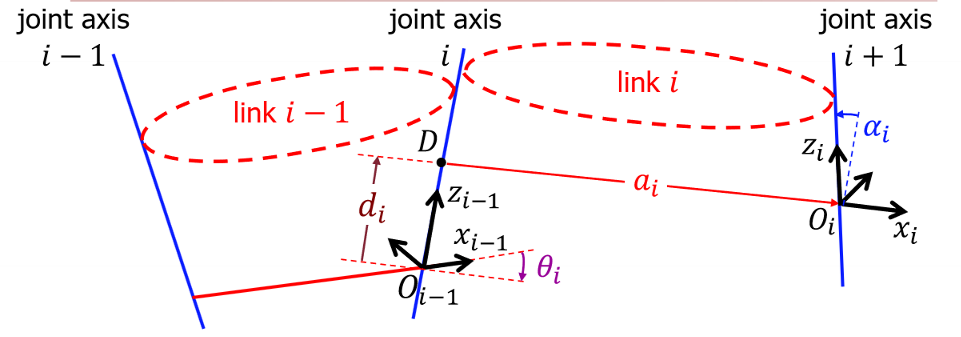

rcz=subs(rcz,rcz,zeros(1,n));  % da cancellare se si vogliono fare calcoli con rcz
%se sono nel piano non ha senso tenere rc_z (cm_z) in 3D si lo
%devo considerare 

uni=ones(1,n);
com=[rcx;rcy;rcz;uni];

if there_is_payload==true           %in questo codice il payload viene gestito in automatico 
    com=[com,[1;1;0;1]]; %se non mi serve la z
    %com=[com,[1;1;1;1]]; %se mi serve la z
end

com

$$com = \left(\begin{array}{ccc} {\mathrm{rcx}}_{1} & {\mathrm{rcx}}_{2} & 1\\ {\mathrm{rcy}}_{1} & {\mathrm{rcy}}_{2} & 1\\ 0 & 0 & 0\\ 1 & 1 & 1 \end{array}\right)$$

%DH_table
DH_table=[-pi/2 0  l1 q1; 0 l2 0 q2 ]

$$DH\_table = \left(\begin{array}{cccc} -\frac{\pi }{2} & 0 & l_{1} & q_{1}\\ 0 & l_{2} & 0 & q_{2} \end{array}\right)$$

%calcolo delle Denavit-Hartemberg Matrices
syms a alpha tetha d real;
DH_param=[alpha a d tetha];

DH_MAT=[cos(tetha) -cos(alpha)*sin(tetha) sin(alpha)*sin(tetha)  a*cos(tetha);
        sin(tetha)  cos(alpha)*cos(tetha) -sin(alpha)*cos(tetha) a*sin(tetha);
        0           sin(alpha)              cos(alpha)                d      ;
        0               0                       0                     1      ];

Array_A = sym('A', [4, 4, n]);
for i=1:n
    DH_MAT_to_sub=subs(DH_MAT,DH_param,DH_table(i,:));
    Array_A(:,:,i)=DH_MAT_to_sub;
end

Array_A;

Adesso possiamo calcolare le componenti dell' energia potenziale:

u = sym('u', [n, 1]);
for i=1:n
    nomeVariabile = ['u' num2str(i)];
    assignin('base', nomeVariabile,u(i,1));
end

syms g G real
G=[-g, 0, 0 ,0]

$$G = \left(\begin{array}{cccc} -g & 0 & 0 & 0 \end{array}\right)$$

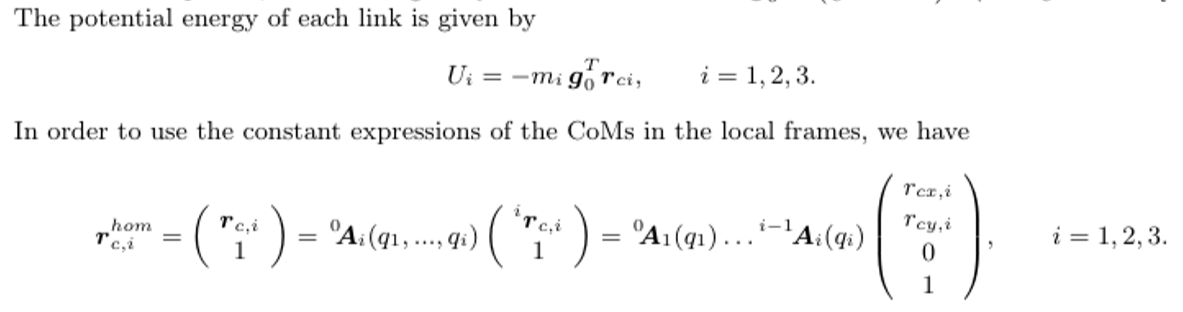

**Calcolo energia potenziale per ogni centro di massa**

for i=1:n
    partial=eye(4);
    for j=1:i
        partial=simplify(partial*Array_A(:,:,j));
    end
    u(i,1)=simplify(m(i,1)*G*partial*com(:,i));
end

if there_is_payload
    if(i==n)
        u=[u;simplify(mp*G*partial*com(:,i+1))]
    end
end

$$u = \left(\begin{array}{c} -g\,m_{1}\,{\mathrm{rcx}}_{1}\,\cos\left(q_{1}\right)\\ -g\,m_{2}\,\cos\left(q_{1}\right)\,\left(l_{2}\,\cos\left(q_{2}\right)+{\mathrm{rcx}}_{2}\,\cos\left(q_{2}\right)-{\mathrm{rcy}}_{2}\,\sin\left(q_{2}\right)\right)\\ -g\,\mathrm{mp}\,\cos\left(q_{1}\right)\,\left(\cos\left(q_{2}\right)-\sin\left(q_{2}\right)+l_{2}\,\cos\left(q_{2}\right)\right) \end{array}\right)$$


u % vettore contenente le energie potenziali

$$u = \left(\begin{array}{c} -g\,m_{1}\,{\mathrm{rcx}}_{1}\,\cos\left(q_{1}\right)\\ -g\,m_{2}\,\cos\left(q_{1}\right)\,\left(l_{2}\,\cos\left(q_{2}\right)+{\mathrm{rcx}}_{2}\,\cos\left(q_{2}\right)-{\mathrm{rcy}}_{2}\,\sin\left(q_{2}\right)\right)\\ -g\,\mathrm{mp}\,\cos\left(q_{1}\right)\,\left(\cos\left(q_{2}\right)-\sin\left(q_{2}\right)+l_{2}\,\cos\left(q_{2}\right)\right) \end{array}\right)$$

total_u=u(1,1);
nn=n;

if there_is_payload
    nn=n+1;
end

for i=2:nn
    total_u=total_u+u(i,1);
end
total_u

$$total\_u = -g\,\mathrm{mp}\,\cos\left(q_{1}\right)\,\left(\cos\left(q_{2}\right)-\sin\left(q_{2}\right)+l_{2}\,\cos\left(q_{2}\right)\right)-g\,m_{2}\,\cos\left(q_{1}\right)\,\left(l_{2}\,\cos\left(q_{2}\right)+{\mathrm{rcx}}_{2}\,\cos\left(q_{2}\right)-{\mathrm{rcy}}_{2}\,\sin\left(q_{2}\right)\right)-g\,m_{1}\,{\mathrm{rcx}}_{1}\,\cos\left(q_{1}\right)$$

gravity_terms=transpose(simplify(jacobian(total_u,q)))

$$gravity\_terms = \left(\begin{array}{c} g\,\mathrm{mp}\,\sin\left(q_{1}\right)\,\left(\cos\left(q_{2}\right)-\sin\left(q_{2}\right)+l_{2}\,\cos\left(q_{2}\right)\right)+g\,m_{2}\,\sin\left(q_{1}\right)\,\left(l_{2}\,\cos\left(q_{2}\right)+{\mathrm{rcx}}_{2}\,\cos\left(q_{2}\right)-{\mathrm{rcy}}_{2}\,\sin\left(q_{2}\right)\right)+g\,m_{1}\,{\mathrm{rcx}}_{1}\,\sin\left(q_{1}\right)\\ g\,m_{2}\,\cos\left(q_{1}\right)\,\left({\mathrm{rcy}}_{2}\,\cos\left(q_{2}\right)+l_{2}\,\sin\left(q_{2}\right)+{\mathrm{rcx}}_{2}\,\sin\left(q_{2}\right)\right)+g\,\mathrm{mp}\,\cos\left(q_{1}\right)\,\left(\cos\left(q_{2}\right)+\sin\left(q_{2}\right)+l_{2}\,\sin\left(q_{2}\right)\right) \end{array}\right)$$

%syms a6 a7;
%gravity_terms=[g*a6*sin(q1)+g*sin(q2)*sin(q1)*a7;g*a7*cos(q1)*cos(q2)]
%serviva per un altro codice, quindi ho cambiato i gravity terms (era l' esonero sbagliato!!)

To find the **EQUILIBRIUM CONFIGURATION **we can costruct the system of equation given by:

%ATTENZIONE costruire il sistema manualmente

    eq1 = 0 == gravity_terms(1,1);
    eq2 = 0 == gravity_terms(2,1);
   % eq3 = 0 == gravity_terms(3,1);
    %eq3 = 0 == gravity_terms(4,1)
solutions = solve([eq1, eq2], [q1, q2])

solutions = struct with fields:
    q1: [8×1 sym]
    q2: [8×1 sym]


%solutions = solve([eq1, eq2,eq3], [q1, q2,q3])
%solutions = solve([eq1, eq2,eq3,eq4], [q1, q2,q3,q4])

solutions.q1

$$ans = \left(\begin{array}{c} 0\\ -\frac{\pi }{2}\\ \frac{\pi }{2}\\ \pi \\ \pi \\ 0\\ -\frac{\pi }{2}\\ \frac{\pi }{2} \end{array}\right)$$

solutions.q2

Attento perche conviene sempre farlo a mano per verificare se hai altre soluzioni dovute dalla presenza di seni e coseni 

Adesso se hai un esercizio come midterm 2022

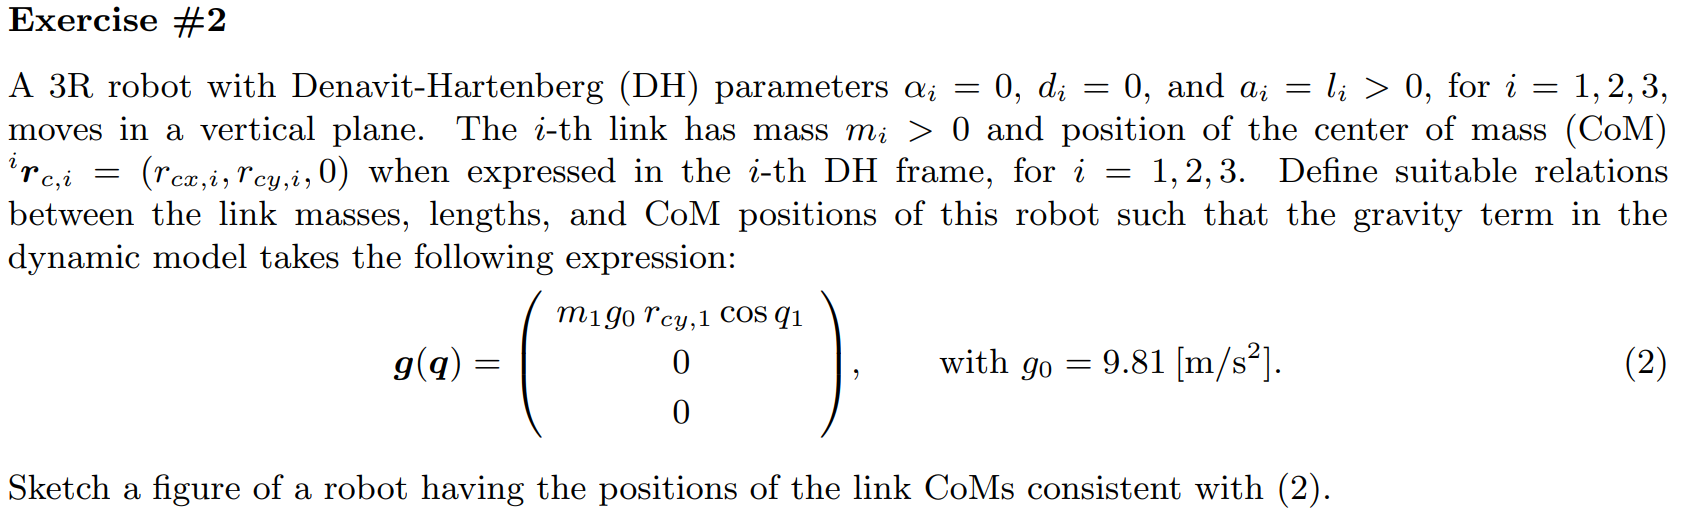

dobbiamo essenzialmente eugugliare le equazioni della nostra energia potenziale con quelli forniti nell' esercizio, per farlo:

Devi partire dall' equazione più facile, purtroppo matalb non è molto capace nel farlo e infatti devi procedere A MANO

Nel nostro caso consideriamo quindi la terza equazione (la piu corta e facile) e la uguagliamo a zero ottenendo le relazioni:


$$l_3=-r_{cx3}  \quad \quad e \quad \quad r_{cy3}=0$$


Adesso devo essenzialmente sostituire questi valori nelle altre equazioni e proseguire nella risoluzione:

% simplify(subs(G_2,[l3,rcy3],[-rcx3,0]))
% newG_1=simplify(subs(G_1,[l3,rcy3],[-rcx3,0]))

Qui siamo praticamente obbligati a risolvere la seconda equazione =0, nel farlo A MANO si ottengono le seguenti relazioni:


$$r_{cy2}=0  \quad \quad e \quad \quad (m_3+m_2)l_2=-r_{cx2}m_2$$


adesso sostituiamo questi valori nella prima equazione (a cui abbiamo precedentemente sostituito le relazioni trovate nella terza) . Scegliendo:


$$l_1*(m_1+m_2+m_3)=-r_{cx1}m_1$$
 

Mi ritorvo con:


$$gm_1r_{cy1}sin(q1)=m_1gr_{cy1}cos(q1)$$


Mi accorgo che i due termini sono perfettamente uguali a meno della funzione seno e coseno, per cui l' intuizione che mi dovrebbe venire è che abbiamo fatto tutto giusto ma il professore ha girato il riferimento e ha considerato l' asse x verticale. Noi abbiamo considerato l' asse y come verticale, infatti questo lo si nota dal termine gravitazionale $g=(0 \ g \ 0 )^T$. Quindi facciamo noi anche la stessa scelta del professore usando $g=(g \ 0 \ 0)^T$, 

e notiamo che nella prima equazione dell' energia potenziale quel sin($q_1$) diventa $cos(q_1)$ confermando tutte le altre scelte.

Adesso per disegnare la situazione prima di tutto diamo dei valori alle cose. 

**RICORDA CHE IL CENTRO DI MASSA DEL LINK 1 è ESPRESSO NEL FRAME 1 NON NEL FRAME 0 E COSI VIA.**

Adesso prendiamo tutte le relazioni che abbiamo definito e diamo dei valori alle cose:


$$l_3=-r_{cx3}  \quad \quad e \quad \quad r_{cy3}=0$$



$$r_{cy2}=0  \quad \quad e \quad \quad (m_3+m_2)l_2=-r_{cx2}m_2$$



$$l_1*(m_1+m_2+m_3)=-r_{cx1}m_1$$
 

Consideriamo $l_1=l_2=l_3=1 [m]$  e $l_1=l_2=l_3=1 [m]$. Ricordiamo che il nostro Obiettivo è soddisfare tutte queste relazioni, quindi posso farlo in vari modi, ora si è deciso di fissare lunghezze dei link e masse.

Quindi dobbiamo trovare i centri di massa dei link, visto che abbiamo fissato tutto il resto. Con queste scelte si ha:


$$r_{cx3}=-1  \quad \& \quad r_{cy3}=0$$



$$r_{cx2}=-2 \quad \& \quad r_{cy2}=0$$



$$r_{cx1}=-3  \quad\& \quad r_{cy1}=arbitrario=0$$


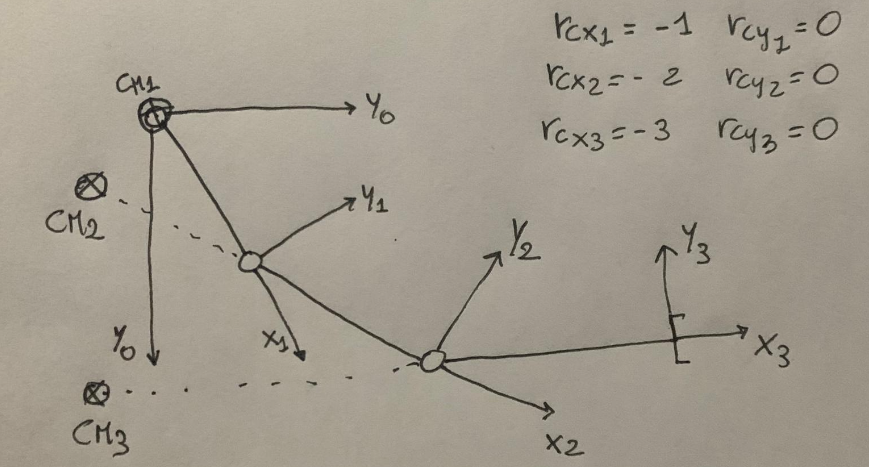

Con altre scelte si ottiene un risultato più fattibile, come per esempio: